%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:\data\kwave\config\t_pos_2board.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\kgrid.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\sourse_wave.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\rfdata.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\medium.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\kgrid.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\sourse_wave.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = [0,2,4,6,8,10,12,14];
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
reference_point = zeros(num_echo_receiver,num_depth,length(rate_IMCL));
reference_point_lowerlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
focal_signal_total = zeros(length(rate_IMCL),num_depth);
focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_total = zeros(length(rate_IMCL),num_depth);
focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));

for kk = 1:length(rate_IMCL)
    v_reference(1,kk) = v_muscle*(1-rate_IMCL(kk)/100) + v_fat*(rate_IMCL(kk)/100);
    for ii = 1:num_depth
        focal_depth(1,ii) = (ii+3)*kgrid.dx;
        focal_point = [0;t_pos(2,1)-focal_depth(1,ii)];
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point);
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(jj,ii,kk) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
            reference_point_upperlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:,ii,kk) = focused_rfdata(1:read_range_rfdata,:,ii,kk)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        hilb_rfdata = hilbert(focused_rfdata(:,:,ii,kk));
        focused_rfdata_amp(:,:,ii,kk) = abs(hilb_rfdata);
        %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
        focused_rfdata_amp_masked(:,:,ii,kk) = focused_rfdata_amp(:,:,ii,kk);
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_amp_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_amp_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_lowerlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
        end
        [~,point_maxAmp_in_mask(:,ii,kk)] = max(focused_rfdata_amp_masked(:,:,ii,kk),[],1);
        for jj = 1:length(target_element)
            %受信ビームフォーミング（整相加算のため）
            focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                focused_rfdata(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_amp(kk,ii,target_element(jj)) = ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            %均質性評価指標
            homogeneity_percel(kk,ii,jj) = abs(point_maxAmp_in_mask(jj,ii,kk) - reference_point(jj,ii));
        end
        homogeneity_total(kk,ii) = sum(homogeneity_percel(kk,ii,:))/length(target_element);
    end
end

## 結果を考察するための動画を作成

IMCL: 4 %のときで考える．包絡線の最大値focused_rfdata_amp_maskedを表示．

clear mov;
fr(1:num_depth) = struct('cdata',[],'colormap',[]);
target_element = 0;
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1);
for ii = 1:num_depth
    figure(1)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_amp_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    %     colorbar;
    %     h_bar = colorbar;
    %     h_bar.Location = 'west';
    %     a1.Position(3:4) = [0.7750 0.3412];
    %     h_bar.Position(1) = 0.94;
    caxis([0.1 max(max(focused_rfdata_amp_masked(:,:,ii)))]);
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    pause(0.05);
    drawnow;
    fr(ii) = getframe(gcf);
end
% play movie
figure;
movie(fr)
% save movie
cd('H:/result/2018_10_21_search_path_contain_only_IMCL')
mv = VideoWriter('search_path_contain_only_IMCL_IMCL4%_noclorbar','MPEG-4');
mv.FrameRate = 3; % ← fpsと同じ %ART:3
% mv.Quality = 100;
open(mv)
writeVideo(mv,fr)
close(mv)

IMCL: 4 %のときで考える．RF信号のfocused_rfdata_maskedを表示．マーカーは包絡線の最大値の位置のまま．

clear mv;
clear fr;
fr(num_depth*3) = struct('cdata',[],'colormap',[]);
target_element = 0;
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1)+1;
for ii = 1:num_depth
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,3))) max(max(focused_rfdata_masked(:,:,ii,3)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,3))) max(max(focused_rfdata_masked(:,:,ii,3)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-1) = getframe(gcf);
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,3))) max(max(focused_rfdata_masked(:,:,ii,3)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii) = getframe(gcf);
end
% play movie
% figure;
% movie(fr)
% save movie
cd('H:/result/2018_10_21_search_path_contain_only_IMCL')
mv = VideoWriter('search_path_contain_only_IMCL_IMCL4%_noclorbar_rfsignal','MPEG-4');
mv.FrameRate = 9; % ← fpsと同じ %ART:3
% mv.Quality = 100;
open(mv)
writeVideo(mv,fr)
close(mv)

2018/11/05

## ex2018_10_22_IMCL_estimation_lateral_fixed_center_f1.0_4.m

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:\data\kwave\config\t_pos_2board.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\kgrid.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\sourse_wave.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\rfdata.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\medium.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\kgrid.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\sourse_wave.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = [0,2,4,6,8,10,12,14];
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
reference_point = zeros(num_echo_receiver,num_depth,length(rate_IMCL));
reference_point_lowerlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
focal_signal_total = zeros(length(rate_IMCL),num_depth);
focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_total = zeros(length(rate_IMCL),num_depth);
focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));

for kk = 1:length(rate_IMCL)
    v_reference(1,kk) = v_muscle*(1-rate_IMCL(kk)/100) + v_fat*(rate_IMCL(kk)/100);
    for ii = 1:num_depth
        focal_depth(1,ii) = (ii+3)*kgrid.dx;
        focal_point = [0;t_pos(2,1)-focal_depth(1,ii)];
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point);
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(jj,ii,kk) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
            reference_point_upperlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:,ii,kk) = focused_rfdata(1:read_range_rfdata,:,ii,kk)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        hilb_rfdata = hilbert(focused_rfdata(:,:,ii,kk));
        focused_rfdata_amp(:,:,ii,kk) = abs(hilb_rfdata);
        %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
        focused_rfdata_amp_masked(:,:,ii,kk) = focused_rfdata_amp(:,:,ii,kk);
        focused_rfdata_masked(:,:,ii,kk) = focused_rfdata(:,:,ii,kk);
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_amp_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_amp_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
        end
        [~,point_maxAmp_in_mask(:,ii,kk)] = max(focused_rfdata_amp_masked(:,:,ii,kk),[],1);
        for jj = 1:length(target_element)
            %受信ビームフォーミング（整相加算のため）
            focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                focused_rfdata(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_amp(kk,ii,target_element(jj)) = ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            %均質性評価指標
            homogeneity_percel(kk,ii,jj) = abs(point_maxAmp_in_mask(jj,ii,kk) - reference_point(jj,ii));
        end
        homogeneity_total(kk,ii) = sum(homogeneity_percel(kk,ii,:))/length(target_element);
    end
end

まずは受信波形が整っている時刻において，波形包絡線最大位置と参照点がどれだけの遅延をしているのか確認

焦点深度が7.3 mmにおいて目視で波形の乱れがほとんどないことを確認

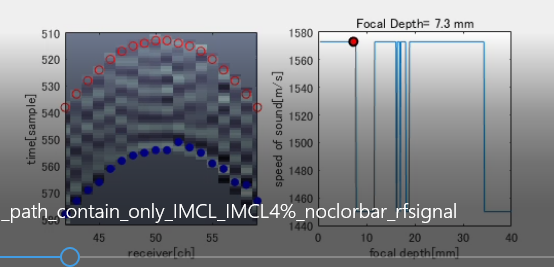

このときの遅延を確認

focal_depth

focal_depth =     0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053


focal_depth(1,70)*1e3 % 70番目が7.3 mmに相当

ans = 7.3000

50 chにおける遅延をみる．

reference_point_50ch = reference_point(50,70,3)

reference_point_50ch = 513

point_maxAmp_in_mask_50ch = point_maxAmp_in_mask(50,70,3)

point_maxAmp_in_mask_50ch = 554

delay_peak_to_read_50ch = point_maxAmp_in_mask_50ch - reference_point_50ch

delay_peak_to_read_50ch = 41

delay_peak_to_read_50ch_sec = delay_peak_to_read_50ch * kgrid.dt

delay_peak_to_read_50ch_sec = 7.8105e-07

focal_depth_of_interest = focal_depth(1,70)

focal_depth_of_interest = 0.0073

focal_depth_of_boundary = focal_depth(1,76)

focal_depth_of_boundary = 0.0079

もう一度IMCLとIMATの境界位置を確認する．

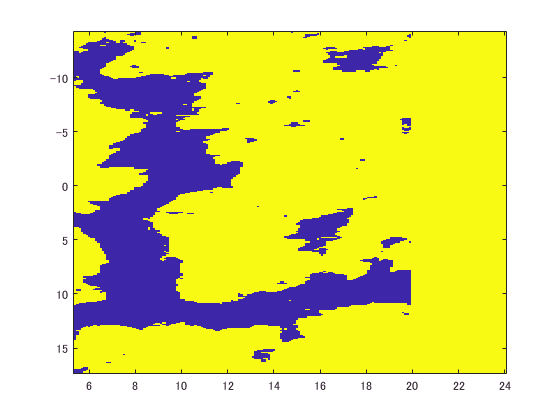

figure;
imagesc(kgrid.x_vec*1e3,kgrid.y_vec*1e3,medium.sound_speed)
xlim([5.3 24.1])
ylim([-14.3 17.4])

x-axis 12.1 mmが境界位置．

20.0 - 12.1

ans = 7.9000

焦点深度7.9 mmがやはり境界位置．

一方で，波形の乱れが出ないために着目している焦点深度は7.3 mm

0.6 * 2 = 1.2 mmだけの遅延が生じているはずである．

筋組織の音速は

v_reference(3)

ans = 1.5748e+03

1,575 m/s であることを加味すると，

(1.2*1e-3)/v_reference(3)

ans = 7.6200e-07

## ex2018_11_05_reference_validation_point_medium6

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:\data\kwave\config\t_pos_2board.mat");
% load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\rfdata.mat");
% load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
% load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\kgrid.mat");
% load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\sourse_wave.mat");
load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\medium.mat");
load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\kgrid.mat");
load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\sourse_wave.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = [0];
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
reference_point = zeros(num_echo_receiver,num_depth,length(rate_IMCL));
reference_point_lowerlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
focal_signal_total = zeros(length(rate_IMCL),num_depth);
focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_total = zeros(length(rate_IMCL),num_depth);
focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));

for kk = 1:length(rate_IMCL)
    v_reference(1,kk) = v_muscle*(1-rate_IMCL(kk)/100) + v_fat*(rate_IMCL(kk)/100);
    for ii = 1:num_depth
        focal_depth(1,ii) = (ii+3)*kgrid.dx;
        focal_point = [0;t_pos(2,1)-focal_depth(1,ii)];
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point);
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(jj,ii,kk) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
            reference_point_upperlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:,ii,kk) = focused_rfdata(1:read_range_rfdata,:,ii,kk)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        hilb_rfdata = hilbert(focused_rfdata(:,:,ii,kk));
        focused_rfdata_amp(:,:,ii,kk) = abs(hilb_rfdata);
        %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
        focused_rfdata_amp_masked(:,:,ii,kk) = focused_rfdata_amp(:,:,ii,kk);
        focused_rfdata_masked(:,:,ii,kk) = focused_rfdata(:,:,ii,kk);
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_amp_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_amp_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
        end
        [~,point_maxAmp_in_mask(:,ii,kk)] = max(focused_rfdata_amp_masked(:,:,ii,kk),[],1);
        for jj = 1:length(target_element)
            %受信ビームフォーミング（整相加算のため）
            focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                focused_rfdata(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_amp(kk,ii,target_element(jj)) = ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            %均質性評価指標
            homogeneity_percel(kk,ii,jj) = abs(point_maxAmp_in_mask(jj,ii,kk) - reference_point(jj,ii));
        end
        homogeneity_total(kk,ii) = sum(homogeneity_percel(kk,ii,:))/length(target_element);
    end
end

青点はRFデータ振幅の最大位置

インデックスが行列の次元を超えています。

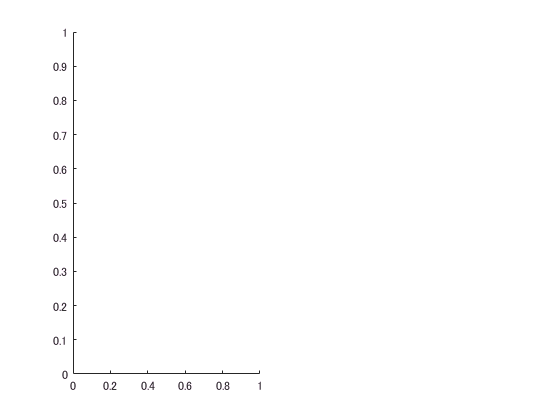

clear mv;
clear fr;
fr(num_depth*3) = struct('cdata',[],'colormap',[]);
target_element = 0;
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1)+1;
for ii = 1:num_depth
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,1));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,1),'red');
    scatter(min(target_element):max(target_element),point_maxRF_in_mask(min(target_element):max(target_element),ii,1),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,1) reference_point_upperlimit(min(target_element),ii,1)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,1))) max(max(focused_rfdata_masked(:,:,ii,1)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,1));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,1),'red');
    scatter(min(target_element):max(target_element),point_maxRF_in_mask(min(target_element):max(target_element),ii,1),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,1) reference_point_upperlimit(min(target_element),ii,1)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,1))) max(max(focused_rfdata_masked(:,:,ii,1)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-1) = getframe(gcf);
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,1));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,1),'red');
    scatter(min(target_element):max(target_element),point_maxRF_in_mask(min(target_element):max(target_element),ii,1),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,1) reference_point_upperlimit(min(target_element),ii,1)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,1))) max(max(focused_rfdata_masked(:,:,ii,1)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii) = getframe(gcf);
end

% play movie
% figure;
% movie(fr)
% save movie
cd('H:/result/2018_11_05_search_path_contain_only_IMCL2')
mv = VideoWriter('validate_rfdata_reference_point_medium_noclorbar_rfsignal','MPEG-4');
mv.FrameRate = 9; % ← fpsと同じ %ART:3
% mv.Quality = 100;
open(mv)
writeVideo(mv,fr)
close(mv)

送受信フォーカスは良好に機能していることが確認できた．

## ex2018_11_05_search_IMAT_including_in_ROI5.m

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
%update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:\data\kwave\config\t_pos_2board.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\kgrid.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\sourse_wave.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\rfdata.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\medium.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\kgrid.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\sourse_wave.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = [4];
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
reference_point = zeros(num_echo_receiver,num_depth,length(rate_IMCL));
reference_point_lowerlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
focal_signal_total = zeros(length(rate_IMCL),num_depth);
focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_total = zeros(length(rate_IMCL),num_depth);
focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));

for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end
for kk = 1:length(rate_IMCL)
    v_reference(1,kk) = v_muscle*(1-rate_IMCL(kk)/100) + v_fat*(rate_IMCL(kk)/100);
    for ii = 1:num_depth
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(jj,ii,kk) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
            reference_point_upperlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:,ii,kk) = focused_rfdata(1:read_range_rfdata,:,ii,kk)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        hilb_rfdata = hilbert(focused_rfdata(:,:,ii,kk));
        focused_rfdata_amp(:,:,ii,kk) = abs(hilb_rfdata);
        %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
        focused_rfdata_amp_masked(:,:,ii,kk) = focused_rfdata_amp(:,:,ii,kk);
        focused_rfdata_masked(:,:,ii,kk) = focused_rfdata(:,:,ii,kk);
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_amp_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_amp_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
        end
        [~,point_maxAmp_in_mask(:,ii,kk)] = max(focused_rfdata_amp_masked(:,:,ii,kk),[],1);
        for jj = 1:length(target_element)
            %受信ビームフォーミング（整相加算のため）
            focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
            focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                focused_rfdata(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
            focal_amp(kk,ii,target_element(jj)) = ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
            %均質性評価指標
            homogeneity_percel(kk,ii,jj) = abs(point_maxAmp_in_mask(jj,ii,kk) - reference_point(jj,ii,kk));
        end
        homogeneity_total(kk,ii) = sum(homogeneity_percel(kk,ii,:))/length(target_element);
    end
end

送受信フォーカスの際に伝播経路中にIMAT領域がどれだけ混在しているかを確認する．

まずは焦点深度7.9 mmのみに関して確認する．

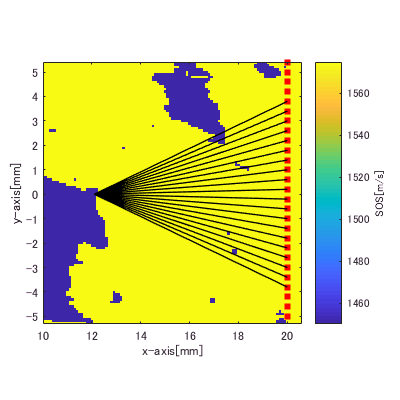

load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('x-axis[mm]')
ylabel('y-axis[mm]')
c = colorbar;
c.Label.String = 'SOS[m/s]';
set(gca,'YDir','normal')
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1)+1;
target_element = find((-focal_depth(1,k)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,k)/2)));
num_target_element = length(target_element);
hold on
for ii = 1:num_target_element
    plot([t_pos(2,target_element(1,ii))*1000;focal_point(2,k)*1000],[t_pos(1,target_element(1,ii))*1000;focal_point(1,k)*1000],'k','LineWidth',1);
end
exportfig("H:\result\2018_11_05_search_path_contain_only_IMCL2\propagation_path_wholeview_focaldepth_7.9mm_on_boundary",'png',[400,400]);
xlim([10.0 20.6])
ylim([-5.3 5.4])
exportfig("H:\result\2018_11_05_search_path_contain_only_IMCL2\propagation_path_detail_focaldepth_7.9mm_on_boundary",'png',[400,400]);

うまく行ったら，これを関数化していつでも気軽に呼び出せるようにする．

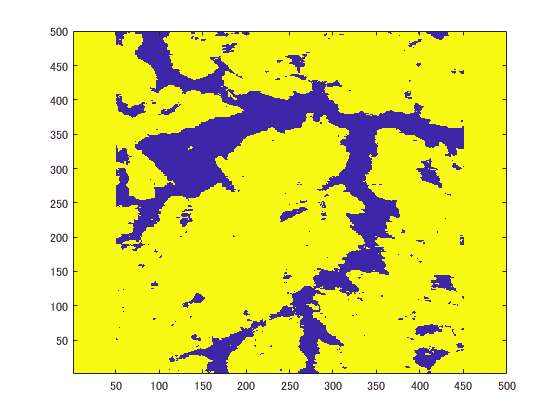

figure;
imagesc(medium.sound_speed);
set(gca,'YDir','normal');

ind_edge_aperture_start = zeros(2,1);
ind_edge_aperture_end = zeros(2,1);
ind_focalpoint = zeros(2,1);

ind_edge_aperture_start(1,1) = find(single(kgrid.x_vec) == t_pos(2,target_element(1)))-1;
ind_edge_aperture_end(1,1) = find(single(kgrid.x_vec) == t_pos(2,target_element(end)))-1;
ind_focalpoint(1,1) = find(single(kgrid.x_vec) == single(focal_point(1,76)));
ind_edge_aperture_start(2,1) = find(single(kgrid.x_vec) == t_pos(1,target_element(1)));
ind_edge_aperture_end(2,1) = find(single(kgrid.x_vec) == t_pos(1,target_element(end)));
ind_focalpoint(2,1) = find(single(kgrid.x_vec) == single(focal_point(2,76)));

X = [ind_focalpoint(2) ind_edge_aperture_start(1)];
V = [ind_focalpoint(1) ind_edge_aperture_start(2)];
Xq = (ind_focalpoint(2):1:ind_edge_aperture_start(1));
vq = floor(interp1(X,V,Xq,'linear'));

変数名を工夫する．後で次元数も反映する．

ind_boundary_paths_start = [Xq;vq];
X = [ind_focalpoint(2) ind_edge_aperture_end(1)];
V = [ind_focalpoint(1) ind_edge_aperture_end(2)];
Xq = (ind_focalpoint(2):1:ind_edge_aperture_end(1));
vq = ceil(interp1(X,V,Xq,'linear'));
ind_boundary_paths_end = [Xq;vq];
rate_IMAT_in_paths = 0;

列方向(y軸方向)に着目して，その間にあるIMATをカウントする．

for ii = 1:length(Xq)
    rate_IMAT_in_paths = rate_IMAT_in_paths + ...
        length(find(medium.sound_speed(ind_boundary_paths_start(2,ii):ind_boundary_paths_end(2,ii),Xq(1,ii)) == v_fat))...
        /(ind_boundary_paths_end(2,ii)-ind_boundary_paths_start(2,ii)+1)...
        /length(Xq)*100;
end
rate_IMAT_in_paths

rate_IMAT_in_paths = 2.5787

経路中のIMATを除去する．

den_muscle = 1040;%筋肉の密度[kg/m3]
den_fat = 920;%脂肪の密度[kg/m3]
den_reference = den_muscle + (den_fat - den_muscle)*rate_IMCL/100;

for ii = 1:length(Xq)
    for jj = int16(ind_boundary_paths_start(2,ii)):int16(ind_boundary_paths_end(2,ii))
        medium.sound_speed(jj,int16(Xq(1,ii)))=v_reference;
        medium.density(jj,int16(Xq(1,ii))) = den_reference;
    end
end
rate_IMAT_in_paths = 0;
for ii = 1:length(Xq)
    rate_IMAT_in_paths = rate_IMAT_in_paths + ...
        length(find(medium.sound_speed(ind_boundary_paths_start(2,ii):ind_boundary_paths_end(2,ii),Xq(1,ii)) == v_fat))...
        /(ind_boundary_paths_end(2,ii)-ind_boundary_paths_start(2,ii)+1)...
        /length(Xq)*100;
end
rate_IMAT_in_paths

rate_IMAT_in_paths = 0

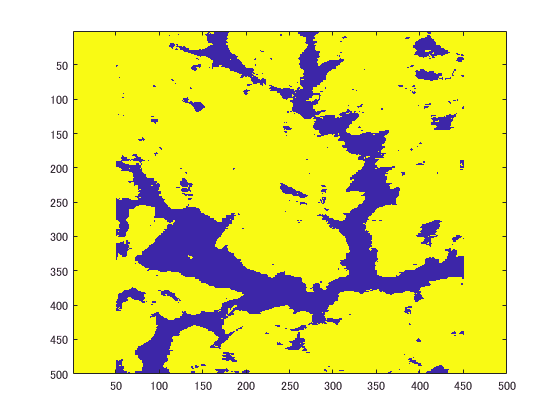

figure;
imagesc(medium.sound_speed);

clear mv;
clear fr;
fr(num_depth*3) = struct('cdata',[],'colormap',[]);
target_element = 0;
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1)+1;
for ii = 1:num_depth
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,1));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,1),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,1),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,1) reference_point_upperlimit(min(target_element),ii,1)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,1))) max(max(focused_rfdata_masked(:,:,ii,1)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,1));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,1),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,1),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,1) reference_point_upperlimit(min(target_element),ii,1)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,1))) max(max(focused_rfdata_masked(:,:,ii,1)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-1) = getframe(gcf);
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,1));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,1),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,1),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,1) reference_point_upperlimit(min(target_element),ii,1)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,1))) max(max(focused_rfdata_masked(:,:,ii,1)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii) = getframe(gcf);
end
% play movie
% figure;
% movie(fr)
% save movie
cd('H:/result/2018_11_05_search_path_contain_only_IMCL2')
mv = VideoWriter('search_path_contain_only_IMCL_IMCL4%_noclorbar_rfsignal_delete_IMAT_in_paths','MPEG-4');
mv.FrameRate = 9; % ← fpsと同じ %ART:3
% mv.Quality = 100;
open(mv)
writeVideo(mv,fr)
close(mv)